Setup

cd('C:\Users\tamar\Documents\GitHub\rFASTCORMICS')
addpath(genpath(pwd))

%optional
set(0,'defaultTextInterpreter','none')
set(groot,'defaulttextinterpreter','none');
set(groot, 'DefaultAxesTickLabelInterpreter', 'none')
set(groot, 'defaultLegendInterpreter','none');

feature astheightlimit 2000

ans = 'feature astHeightLimit 2000'


altcolor= [255 255 255;255 204 204; 255 153 153; 255 102 102; 255 51 51;...
    255 0 0; 204 0 0; 152 0 0; 102 0 0;  51 0 0]/255; %shorter 10% = 1 bar

## 3.1 Expression data input

Import the gene expression data into Matlab. 

data_cancer = readtable('fpkm_BRCA_cancer.txt', "ReadRowNames",true)

data_cancer = 23368×10 table
                   BRCA_C_TCGA_A8_A0AB_01A_11R_A034_07    BRCA_C_TCGA_AO_A12H_01A_11R_A115_07    BRCA_C_TCGA_E9_A1NC_01A_21R_A26B_07    BRCA_C_TCGA_A1_A0SM_01A_11R_A084_07    BRCA_C_TCGA_A2_A0D0_01A_11R_A00Z_07    BRCA_C_TCGA_A8_A06Y_01A_21R_A00Z_07    BRCA_C_TCGA_C8_A1HO_01A_11R_A13Q_07    BRCA_C_TCGA_D8_A4Z1_01A_21R_A266_07    BRCA_C_TCGA_C8_A1HL_01A_11R_A137_07    BRCA_C_TCGA_B6_A0RH_01A_21R_A115_07
                   ___________________________________    ___________________________________    ___________________________________    ___________________________________    ___________________________________    ___________________________________    ________________________________

data_control = readtable('fpkm_BRCA_control.txt', "ReadRowNames",true)

data_control = 23368×10 table
                   BRCA_H_TCGA_BH_A1EO_11A_31R_A137_07    BRCA_H_TCGA_BH_A0DH_11A_31R_A089_07    BRCA_H_TCGA_BH_A204_11A_53R_A157_07    BRCA_H_TCGA_BH_A0BC_11A_22R_A089_07    BRCA_H_TCGA_BH_A1FG_11B_12R_A13Q_07    BRCA_H_TCGA_BH_A0BA_11A_22R_A19E_07    BRCA_H_TCGA_BH_A0DT_11A_12R_A12D_07    BRCA_H_TCGA_BH_A1F0_11B_23R_A137_07    BRCA_H_TCGA_BH_A203_11A_42R_A169_07    BRCA_H_TCGA_AC_A23H_11A_12R_A157_07
                   ___________________________________    ___________________________________    ___________________________________    ___________________________________    ___________________________________    ___________________________________    _______________________________


data = [data_cancer, data_control]

data = 23368×20 table
                   BRCA_C_TCGA_A8_A0AB_01A_11R_A034_07    BRCA_C_TCGA_AO_A12H_01A_11R_A115_07    BRCA_C_TCGA_E9_A1NC_01A_21R_A26B_07    BRCA_C_TCGA_A1_A0SM_01A_11R_A084_07    BRCA_C_TCGA_A2_A0D0_01A_11R_A00Z_07    BRCA_C_TCGA_A8_A06Y_01A_21R_A00Z_07    BRCA_C_TCGA_C8_A1HO_01A_11R_A13Q_07    BRCA_C_TCGA_D8_A4Z1_01A_21R_A266_07    BRCA_C_TCGA_C8_A1HL_01A_11R_A137_07    BRCA_C_TCGA_B6_A0RH_01A_21R_A115_07    BRCA_H_TCGA_BH_A1EO_11A_31R_A137_07    BRCA_H_TCGA_BH_A0DH_11A_31R_A089_07    BRCA_H_TCGA_BH_A204_11A_53R_A157_07    BRCA_H_TCGA_BH_A0BC_11A_22R_A089_07    BRCA_H_TCGA_BH_A1FG_11B_12R_A13Q_07    BRCA_H_TCGA_BH_A0BA_11A_22R_A19E_07    BRCA_H_TCGA_BH_A0DT_11A_12R_A12D_07    


fpkm = table2array(data)

fpkm = 	1.0e+04 *

    0.0002    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0002    0.0001    0.0000    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0002    0.0005    0.0005    0.0008    0.0001    0.0008    0.0005    0.0006    0.0007    0.0006    0.0001    0.0003    0.0001    0.0001    0.0001    0.0002    0.0003    0.0002    0.0001    0.0001
    0.0001    0.0001    0.0000    0.0001    0.0000    0.0002    0.0001    0.0002    0.0001    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0002    0.0002    0.0002    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0

rownames = data.Properties.RowNames

rownames = 23368×1 cell array
    {'1/2-SBSRNA4'}
    {'A1BG'       }
    {'A1BG-AS1'   }
    {'A1CF'       }
    {'A2LD1'      }
    {'A2M'        }
    {'A2ML1'      }
    {'A2MP1'      }
    {'A4GALT'     }
    {'A4GNT'      }
    {'AA06'       }
    {'AAA1'       }
    {'AAAS'       }
    {'AACS'       }
    {'AACSP1'     }
    {'AADAC'      }
    {'AADACL2'    }
    {'AADACL3'    }
    {'AADACL4'    }
    {'AADAT'      }
    {'AAGAB'      }
    {'AAK1'       }
    {'AAMP'       }
    {'AANAT'      }
    {'AARS'       }
    {'AARS2'      }
    {'AARSD1'     }
    {'AASDH'      }
    {'AASDHPPT'   }
    {'AASS'       }


colnames = data.Properties.VariableNames

colnames = 1×20 cell array
    {'BRCA_C_TCGA_A8_A0AB_01A_11R_A034_07'}    {'BRCA_C_TCGA_AO_A12H_01A_11R_A115_07'}    {'BRCA_C_TCGA_E9_A1NC_01A_21R_A26B_07'}    {'BRCA_C_TCGA_A1_A0SM_01A_11R_A084_07'}    {'BRCA_C_TCGA_A2_A0D0_01A_11R_A00Z_07'}    {'BRCA_C_TCGA_A8_A06Y_01A_21R_A00Z_07'}    {'BRCA_C_TCGA_C8_A1HO_01A_11R_A13Q_07'}    {'BRCA_C_TCGA_D8_A4Z1_01A_21R_A266_07'}    {'BRCA_C_TCGA_C8_A1HL_01A_11R_A137_07'}    {'BRCA_C_TCGA_B6_A0RH_01A_21R_A115_07'}    {'BRCA_H_TCGA_BH_A1EO_11A_31R_A137_07'}    {'BRCA_H_TCGA_BH_A0DH_11A_31R_A089_07'}    {'BRCA_H_TCGA_BH_A204_11A_53R_A157_07'}    {'BRCA_H_TCGA_BH_A0BC_11A_22R_A089_07'}    {'BRCA_H_TCGA_BH_A1FG_11B_12R_A13Q_07'}    {'BRCA_H_TCGA_BH_A0BA_11A_22R_A19E_07'}    {'BRCA_H_TCGA_BH_A0DT_11A_12R_A12D_07'}    {'BRCA_H_TCGA_BH_A1F0_11B_23R_A137_07'}    {'BRCA_H_TCGA_BH_A203_11A_42R_A169_07'}    {'BRCA_H_TCGA_AC_A23H_11A_12R_A157_07'}


discretization step 

% discretized = discretize_FPKM(fpkm, colnames,1) %for figures
discretized = discretize_FPKM(fpkm, colnames) % no figures

discretized =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0    -1     0     0    -1     0     0     0     0     0     0
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
    -1    -1     1    -1    -1    -1    -1    -1    -1     0    -1     0    -1     0    -1    -1    -1    -1     0     0
    -1     0     0    -1     0    -1    -1    -1    -1    -1    -1     0    -1    -1     0    -1    -1    -1    -1    -1
     0     0     1

## 3.2.	Context-specific model reconstruction

human reconstruction Recon 2.04 

can also be downloaded from https://www.vmh.life/files/reconstructions/Recon/2.04/Recon2.v04.mat_.zip. 

load Recon2.v04.mat

consitent model creation

A = fastcc_4_rfastcormics(modelR204, 1e-4,0)

Elapsed time is 153.112962 seconds.


A =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


consistent_model = removeRxns(modelR204, modelR204.rxns(setdiff(1:numel(modelR204.rxns),A)))

consistent_model = struct with fields:
                      S: [2960×5317 double]
                   rxns: {5317×1 cell}
                     lb: [5317×1 double]
                     ub: [5317×1 double]
                    rev: [5317×1 double]
                      c: [5317×1 double]
             rxnGeneMat: [5317×2140 double]
                  rules: {5317×1 cell}
                  genes: {2140×1 cell}
                grRules: {5317×1 cell}
             subSystems: {5317×1 cell}
               rxnNames: {5317×1 cell}
              rxnKeggID: {5317×1 cell}
    rxnConfidenceEcoIDA: {5317×1 cell}
    rxnConfidenceScores: {5317×1 cell}
             rxnsboTerm: {5317×1 cell}
          rxnReferences: {5317×1 cell}
           rxnECNumbers: {5317×1 cell}
               rxnNotes: {5317×1 cell}
                   mets: {2960×1 cell}
                      b: [2960×1 double]
               metNames: {2960×1 cell}
            metFormulas: {2960×1 cell}
              metCharge: [2960×1 double]
   

setting parameters

load medium_example.mat
load dico_ML.mat

epsilon = 1e-4

epsilon = 1.0000e-04

consensus_proportion = 0.9

consensus_proportion = 0.9000


already_mapped_tag = 0

already_mapped_tag = 0

unpenalizedSystems = {'Transport, endoplasmic reticular';
    'Transport, extracellular';
    'Transport, golgi apparatus';
    'Transport, mitochondrial';
    'Transport, peroxisomal';
    'Transport, lysosomal';
    'Transport, nuclear'};
unpenalized = consistent_model.rxns(ismember(consistent_model.subSystems,unpenalizedSystems));
optional_settings.unpenalized = unpenalized;

optional_settings.func = {'DM_atp_c_';'biomass_reaction'}; % forced reactions

not_medium_constrained = 'EX_tag_hs(e)';% if no constrain is used please remove the field.
optional_settings.not_medium_constrained = not_medium_constrained;

optional_settings.medium = medium_example;% if no medium is used please remove the field.

reconstruct the context-specific models

load('model_reconstruction.mat')

consensus models

% [model_cancer, A_final_cancer] = fastcormics_RNAseq(consistent_model, discretized(:,1:10), rownames, dico, already_mapped_tag, consensus_proportion, epsilon, optional_settings)
% [model_control, A_final_control] = fastcormics_RNAseq(consistent_model, discretized(:,11:20), rownames, dico, already_mapped_tag, consensus_proportion, epsilon, optional_settings)
%
% models_keep_consensus = zeros(numel(consistent_model.rxns), 2)
%
% models_keep_consensus(A_final_cancer,1) = 1
% models_keep_consensus(A_final_control,2) = 1

sample-specific models

% for i = 1:numel(colnames) %for each sample
%     [~, A_keep{i}] = fastcormics_RNAseq(consistent_model, discretized(:,i), ...
%         rownames, dico , already_mapped_tag, consensus_proportion, epsilon, optional_settings);
% end
%
% models_keep = zeros(numel(consistent_model.rxns), numel(colnames))
%
% for i=1:numel(colnames)
%     models_keep(A_keep{i},i) = 1
% end

## 3.3.	Basic model and pathway analysis

similarity between two models can be assessed via the Jaccard similarity index

J = squareform(pdist(models_keep','jaccard'));

cgo_J = clustergram(1-J,...
    'RowLabels', colnames,...
    'ColumnLabels', colnames,...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor)

Clustergram object with 20 rows of nodes and 20 columns of nodes.



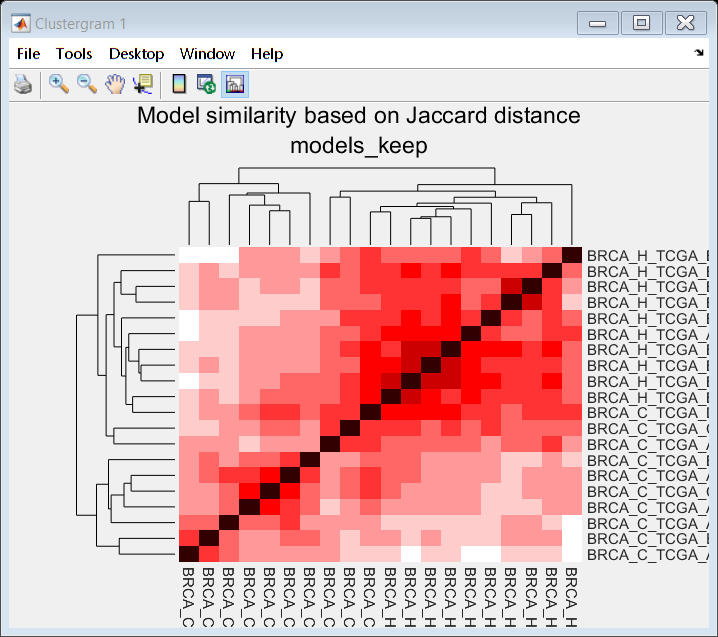

addTitle(cgo_J,{'Model similarity based on Jaccard distance','models_keep'})

Pathway analysis 

Pathways = table(unique(consistent_model.subSystems));
[pathways, ~, ub] = unique(consistent_model.subSystems);
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[I, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.consistent(ia) = T.path_counts(ib);

pathway information for the consensus models

[pathways, ~, ub] = unique(consistent_model.subSystems(find(models_keep_consensus(:,1))));
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[I, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.Var2(ia) = T.path_counts(ib) ;
Pathways.Properties.VariableNames{3} = 'cancer_consensus';

[pathways, ~, ub] = unique(consistent_model.subSystems(find(models_keep_consensus(:,2))));
path_counts = histc(ub, 1:length(pathways));
T = table(pathways, path_counts);
[I, ia, ib] = intersect(Pathways.Var1, T.pathways);
Pathways.Var2(ia) = T.path_counts(ib) ;
Pathways.Properties.VariableNames{4} = 'control_consensus';

pathway information for the sample-specific models

for i=1:numel(colnames)
    [pathways, ~, ub] = unique(consistent_model.subSystems(find(models_keep(:,i))));
    path_counts = histc(ub, 1:length(pathways));
    T = table(pathways, path_counts);
    [I, ia, ib] = intersect(Pathways.Var1, T.pathways);
    Pathways.Var2(ia) = T.path_counts(ib) ;
    Pathways.Properties.VariableNames{4+i} = colnames{i};
end

pathway activity rates

PathwayActivity = Pathways;
for i=3:size(PathwayActivity,2)
    PathwayActivity(:,i) = array2table(table2array(PathwayActivity(:,i))./table2array(PathwayActivity(:,2)));
end
PathwayActivity

### comparison of 2 conditions

pathways with a difference higher than 20% 

diff_idx = find(abs(table2array(PathwayActivity(:,3))- table2array(PathwayActivity(:,4))) > 0.2)

plotting

figure
hold on
scatter(table2array(PathwayActivity(:,3)),table2array(PathwayActivity(:,4)),'filled',...
    'MarkerFaceColor',[0.9 0.9 0.9])
scatter(table2array(PathwayActivity(diff_idx,3)),table2array(PathwayActivity(diff_idx,4)),...
    'black')
ylabel('cancer consensus model')
xlabel('control consensus model')
title('Pathway presence rate in the consensus models')
line([0 1], [0,1],'Color','k')
line([0 0.8], [0.2,1],'Color','k','LineStyle','--')
line([0.2 1], [0,0.8],'Color','k','LineStyle','--')
legend({'All pathways','>20%'},"Location","best")
text(table2array(PathwayActivity(diff_idx,3)),table2array(PathwayActivity(diff_idx,4)), PathwayActivity.Var1(diff_idx))

comparison of multiple samples

cgo = clustergram(table2array(PathwayActivity(:,3:end)),...
    'RowLabels', PathwayActivity.Var1,...
    'ColumnLabels', PathwayActivity.Properties.VariableNames(3:end),...
    'ColumnLabelsRotate',270, ...
    'Cluster', 'all', ...
    'symmetric','False',...
    'Colormap', altcolor)
h = plot(cgo); set(h,'TickLabelInterpreter','none');
colorbar(h)
title(h,'Pathway activity for all models')

## 3.4. In silico gene deletion and drug repurposing

set the biomass reaction as objective function:

model_out = changeObjective(Cmodel,'biomass_reaction')

model_out = struct with fields:
              S: [2960×5317 double]
           rxns: {5317×1 cell}
             lb: [5317×1 double]
             ub: [5317×1 double]
            rev: [5317×1 double]
              c: [5317×1 double]
     rxnGeneMat: [5317×2140 double]
          rules: {5317×1 cell}
          genes: {2140×1 cell}
        grRules: {5317×1 cell}
     subSystems: {5317×1 cell}
       rxnNames: {5317×1 cell}
           mets: {2960×1 cell}
              b: [2960×1 double]
       metNames: {2960×1 cell}
    description: 'Recon 2.04'


set the ATP demand as objective function

model_out = changeObjective(Cmodel,'DM_atp_c_')

model_out = struct with fields:
              S: [2960×5317 double]
           rxns: {5317×1 cell}
             lb: [5317×1 double]
             ub: [5317×1 double]
            rev: [5317×1 double]
              c: [5317×1 double]
     rxnGeneMat: [5317×2140 double]
          rules: {5317×1 cell}
          genes: {2140×1 cell}
        grRules: {5317×1 cell}
     subSystems: {5317×1 cell}
       rxnNames: {5317×1 cell}
           mets: {2960×1 cell}
              b: [2960×1 double]
       metNames: {2960×1 cell}
    description: 'Recon 2.04'


verified with with the checkObjective function 

checkObjective(model_out)

ans = 1×1 cell array
    {'DM_atp_c_'}


## perform the in silico gene deletion 

initialize the solver

changeCobraSolver('ibm_cplex')


 > IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2019b.


ans = logical
   1


 run the single gene deletion

for i=1:size(models_keep,2) %for each model
    
    %ATP
    ind = find(~cellfun(@isempty, regexp(consistent_model.rxns, 'DM_atp_c_')));
    model_out = removeRxns(consistent_model,consistent_model.rxns(setdiff(1:numel(consistent_model.rxns),find(models_keep(:,i))))); % create model based on active reactions
    model_out = changeObjective(model_out,consistent_model.rxns(ind));
    
    [grRatio, grRateKO, grRateWT, hasEffect, delRxns, fluxSolution] = singleGeneDeletion_rFASTCORMICS(model_out,'FBA',[],0,1);
    
    grRatio_ATP(:,i)    = grRatio;
    grRateKO_ATP(:,i)   = grRateKO;
    grRateWT_ATP(:,i)   = grRateWT;
    
    %Biomass
    ind = find(~cellfun(@isempty, regexp(consistent_model.rxns, 'biomass_reaction')));
    model_out = removeRxns(consistent_model,consistent_model.rxns(setdiff(1:numel(consistent_model.rxns),find(models_keep(:,i))))); % create model based on active reactions
    model_out = changeObjective(model_out,consistent_model.rxns(ind));
    
    [grRatio, grRateKO, grRateWT, hasEffect, delRxns, fluxSolution, genelist] = singleGeneDeletion_rFASTCORMICS(model_out,'FBA',[],0,1);
    
    grRatio_biomass(:,i)    = grRatio;
    grRateKO_biomass(:,i)   = grRateKO;
    grRateWT_biomass(:,i)   = grRateWT;
    
end

grRateWT = 15.9467

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 0.6063

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 22.6371

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 0.8890

Single gene deletion analysis in progress ...
100%    [........................................]


grRateWT = 17.8116

Single gene deletion analysis in progress ...
43%     [.................                       ]


sum(grRatio_biomass < 0.5,2)

genes = unique(regexprep(consistent_model.genes,'\..*',''))

essential_genes = genelist(find(sum(grRatio_biomass < 0.5,2)))

[I, ia, ib] = intersect(dico.ENTREZ,essential_genes)

[dico.SYMBOL(ia), essential_genes]